**2D Plotting Basics**

A few commands and functions

- **clear** --> c**l**ears all variables in workspace

- **clc **--> clears the command window

- **close all** --> closes all figures

- **figure** --> opens a new figure

- **clf** --> clears a figure

- **plot(x, y, style)** --> plot vector x vs vector y with variable styles

- **plot(x1, y1, style1, x2, y2, style2) **--> put multiple plots on the same set of axes

- **hold on / hold off** --> multiple plots in the same figure (effectively the same as above)

- **axis** --> change the axis in some way

- **title** --> give the plot a title

- **xlable() **--> lable on the x-axis

- **ylable()** --> lable on the y-axis

- **subplot(row, col, spot) **--> put multiple set of axes on the same diagram

clear %clears all variables in workspace
clc %clears the command window
close all %closes all figures

clf %clears a figure


Basic plot

disp('Basic Data to Plot')

Basic Data to Plot


x1 = [1 3 5 7 9]

x1 =      1     3     5     7     9


y1 =[6 7 4 4 10]

y1 =      6     7     4     4    10



disp('Basic plot of points connected with interpreted line')

Basic plot of points connected with interpreted line


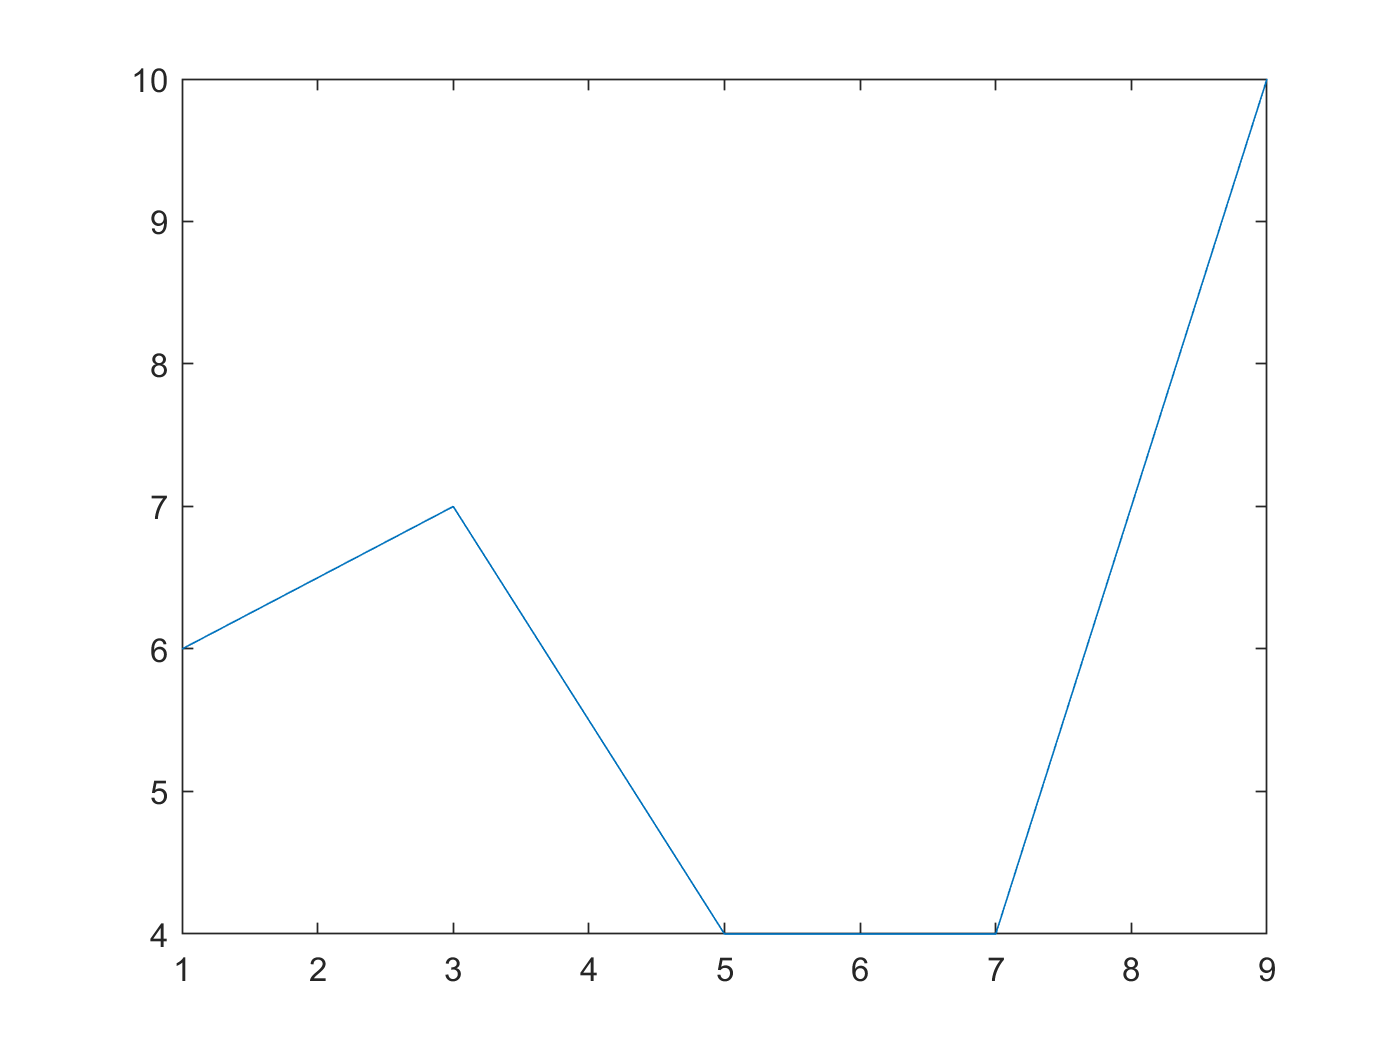

plot(x1,y1)  

Style option

% Tricking it out with style options
%            b     blue          .     point              -     solid
%            g     green         o     circle             :     dotted
%            r     red           x     x-mark             -.    dashdot 
%            c     cyan          +     plus               --    dashed   
%            m     magenta       *     star             (none)  no line
%            y     yellow        s     square
%            k     black         d     diamond
%            w     white         v     triangle (down)
%                                ^     triangle (up)
%                                <     triangle (left)
%                                >     triangle (right)
%                                p     pentagram
%                                h     hexagram


disp('Styled plot - change line color')

Styled plot - change line color


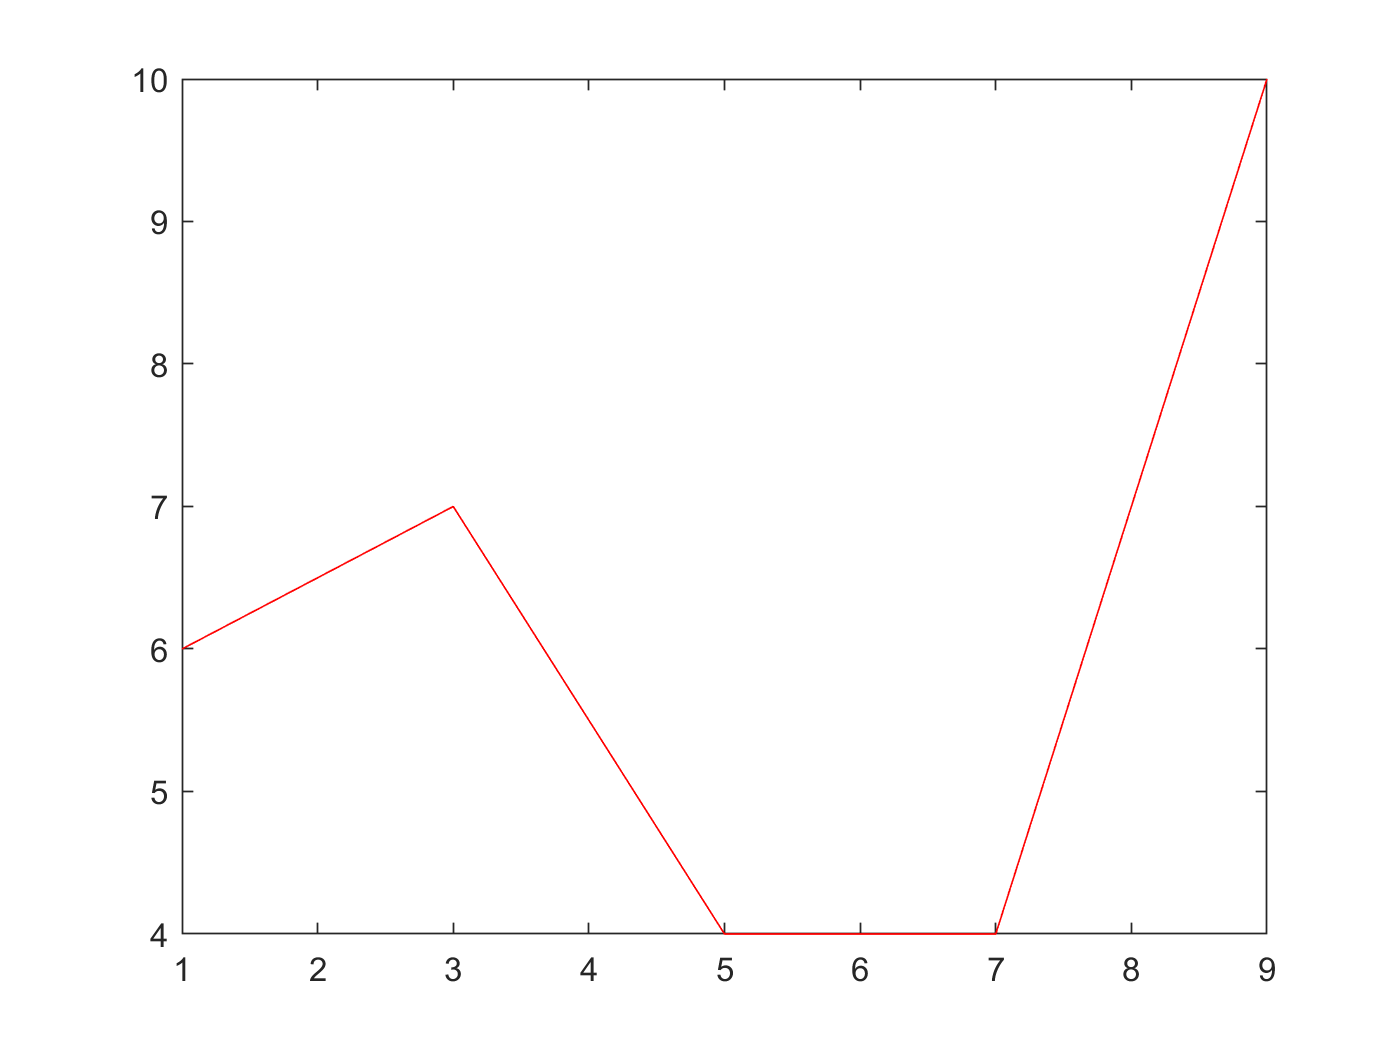

plot(x1,y1,'r') 


disp('Styled plot - change line style')

Styled plot - change line style


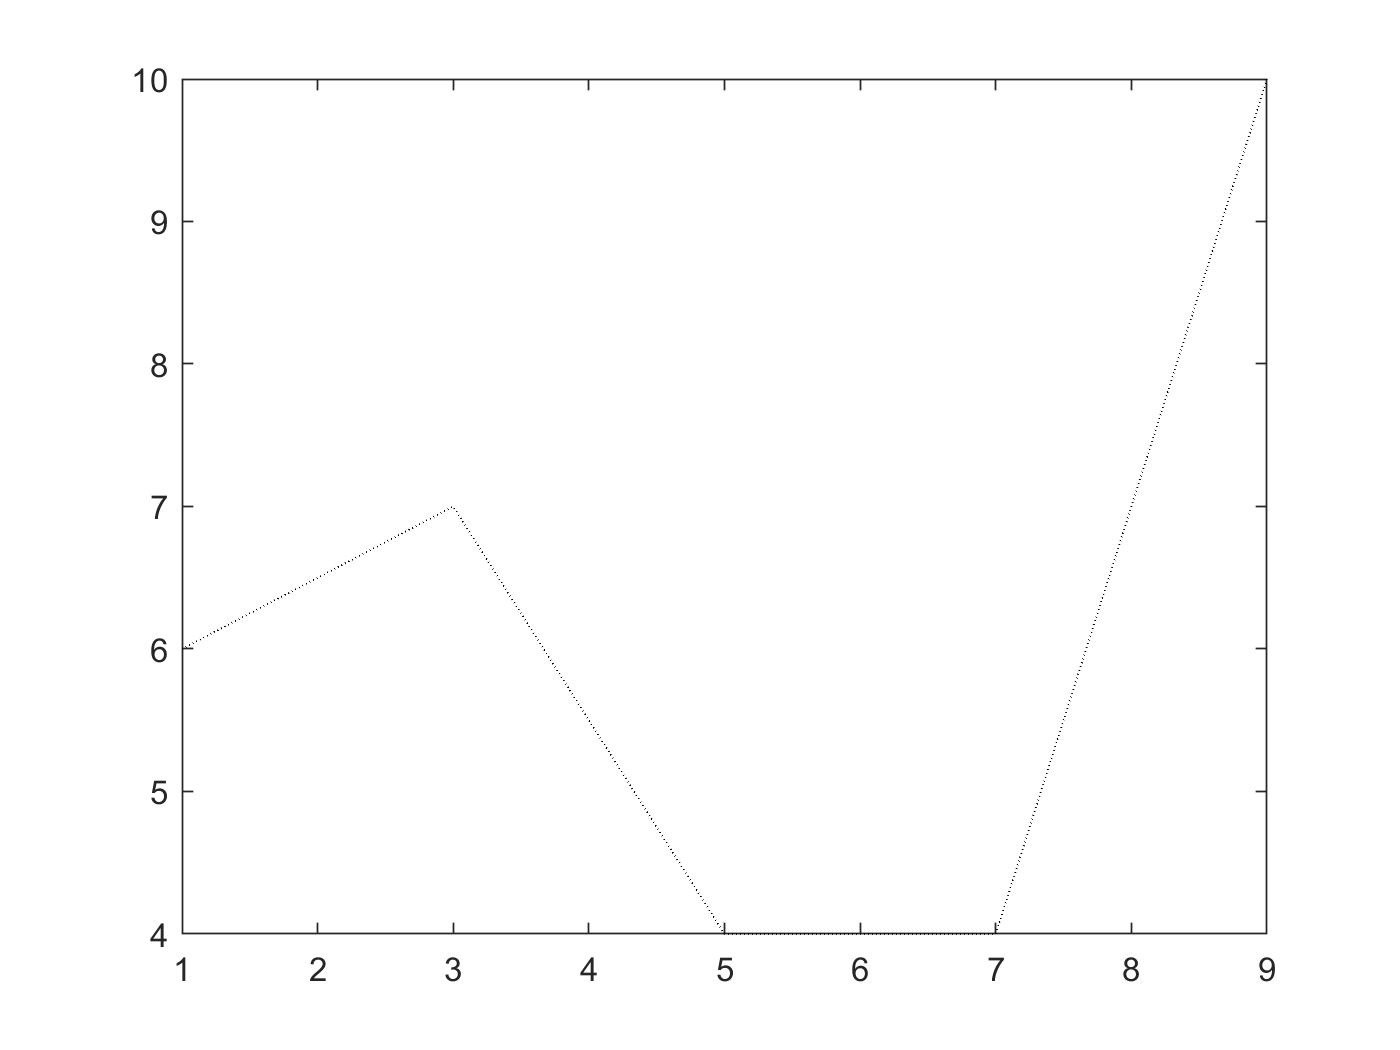

plot(x1,y1,'k:')


disp('Style plot - point marker.')

Style plot - point marker.


disp('*Note when you designate a point marker, the interpredt lines go away')

*Note when you designate a point marker, the interpredt lines go away


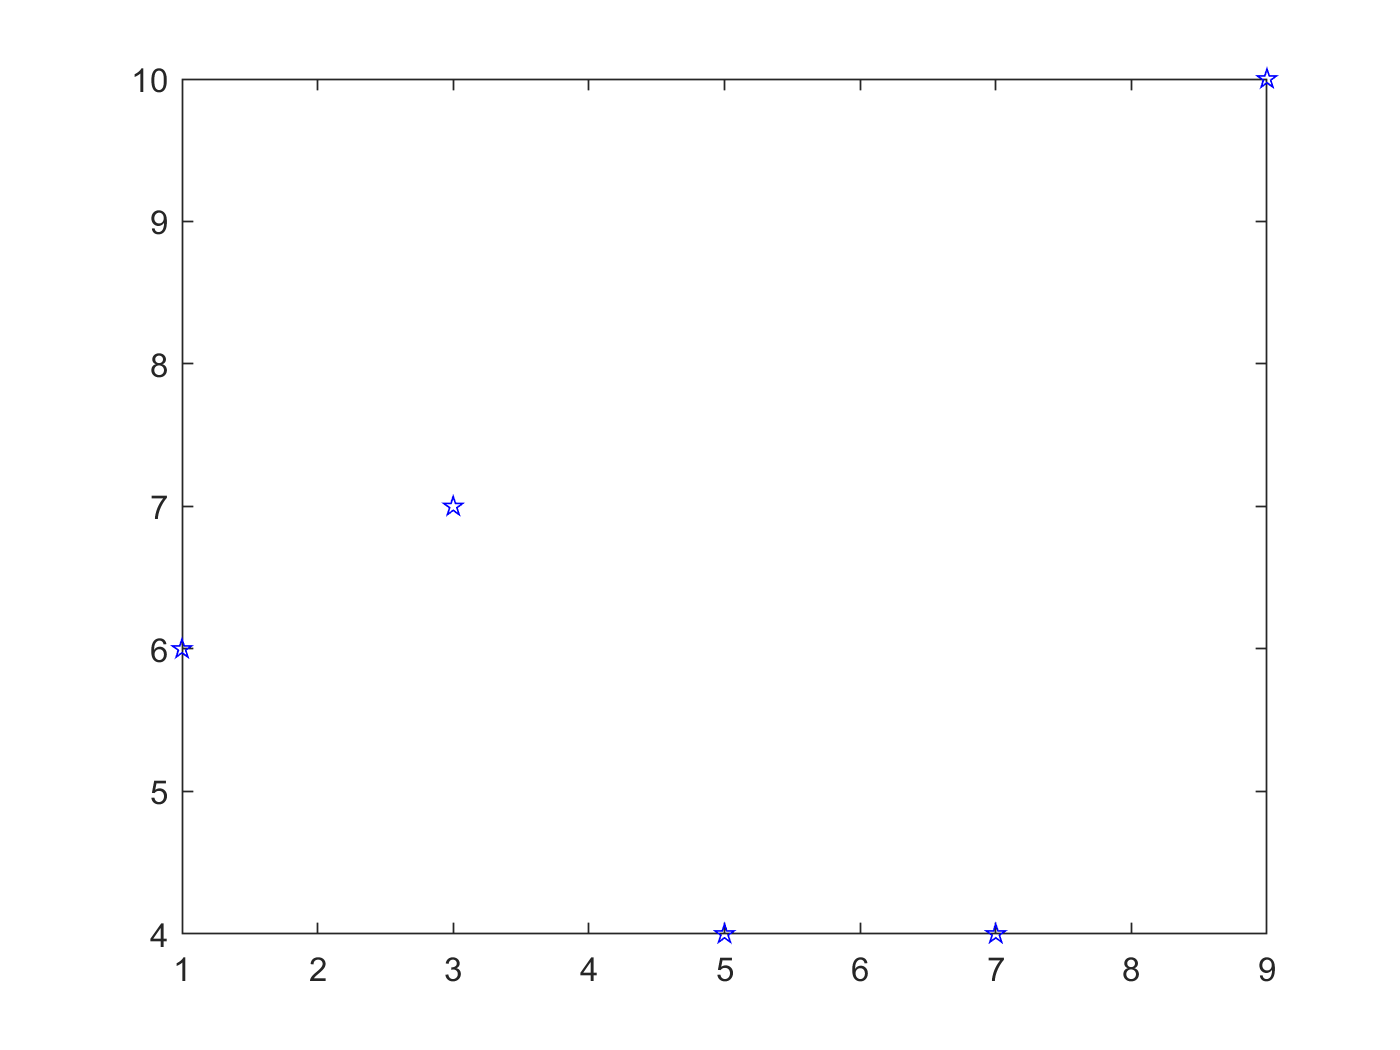

plot(x1,y1,'bp')


disp('Style plot - line color and point marker')

Style plot - line color and point marker


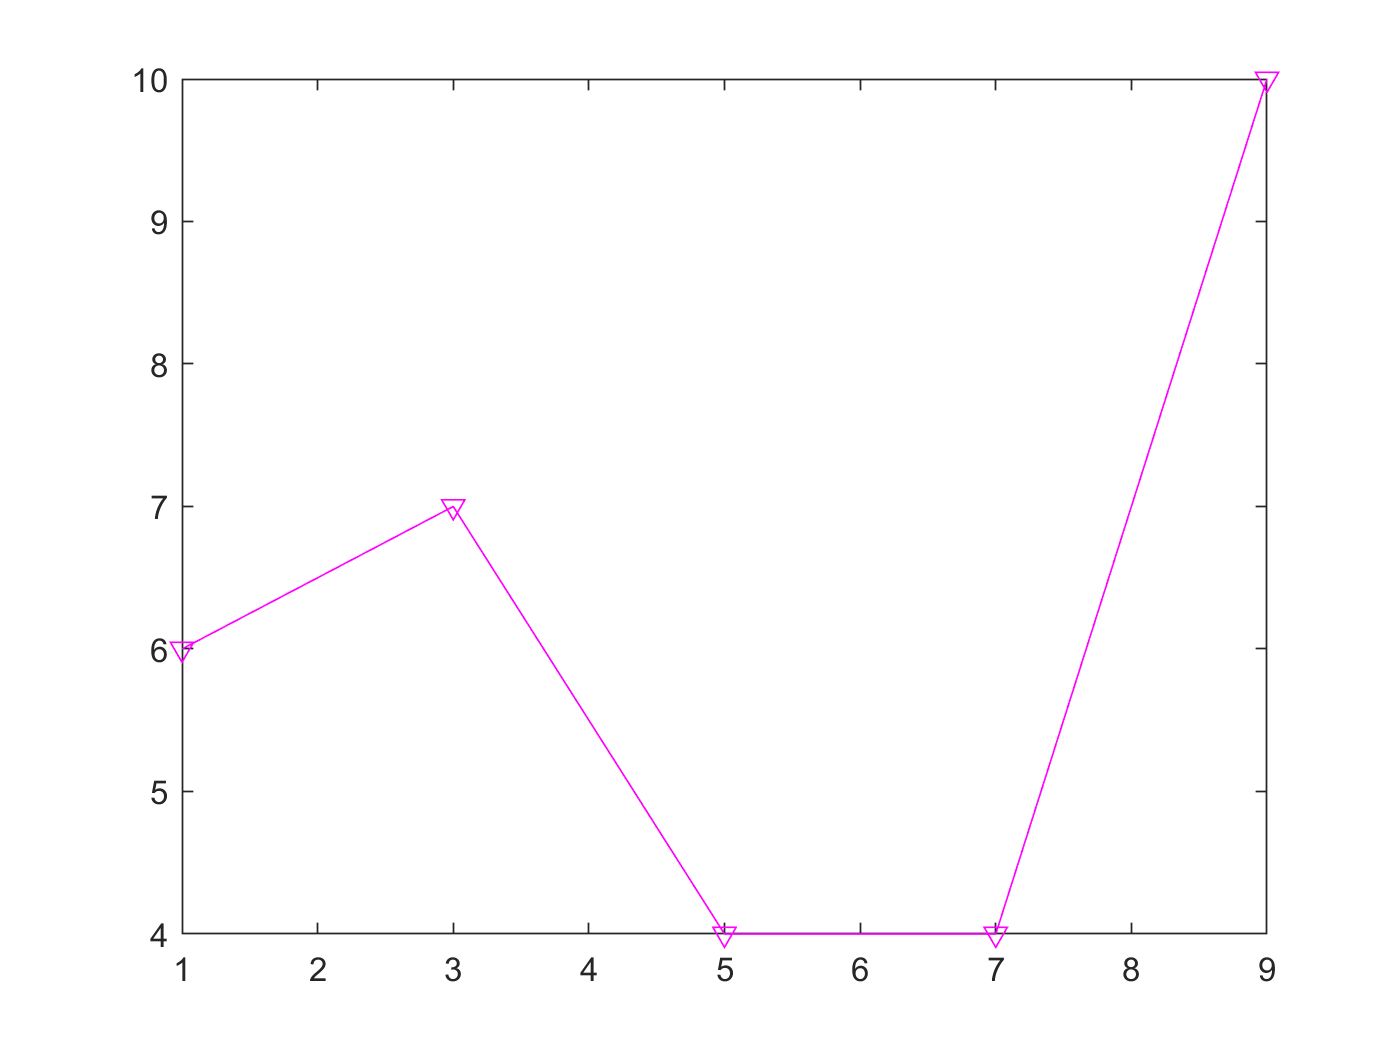

plot(x1,y1,'m-v')

Additonal style options

disp('Control line width')

Control line width


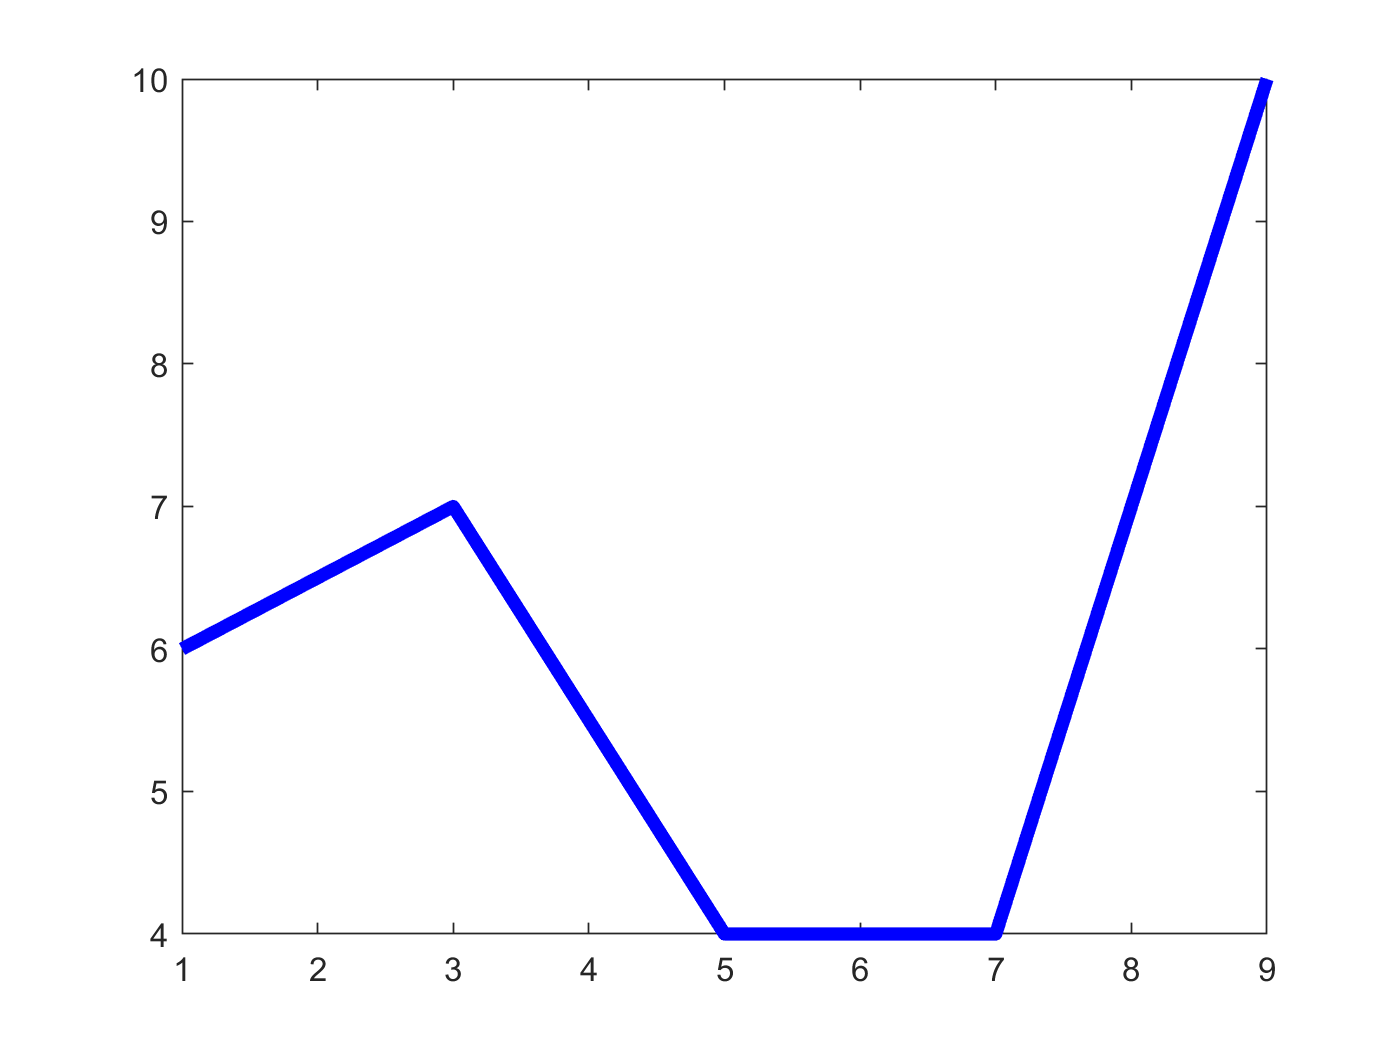

plot(x1,y1,'b','linewidth',4)


disp('Control alot of stuff')

Control alot of stuff


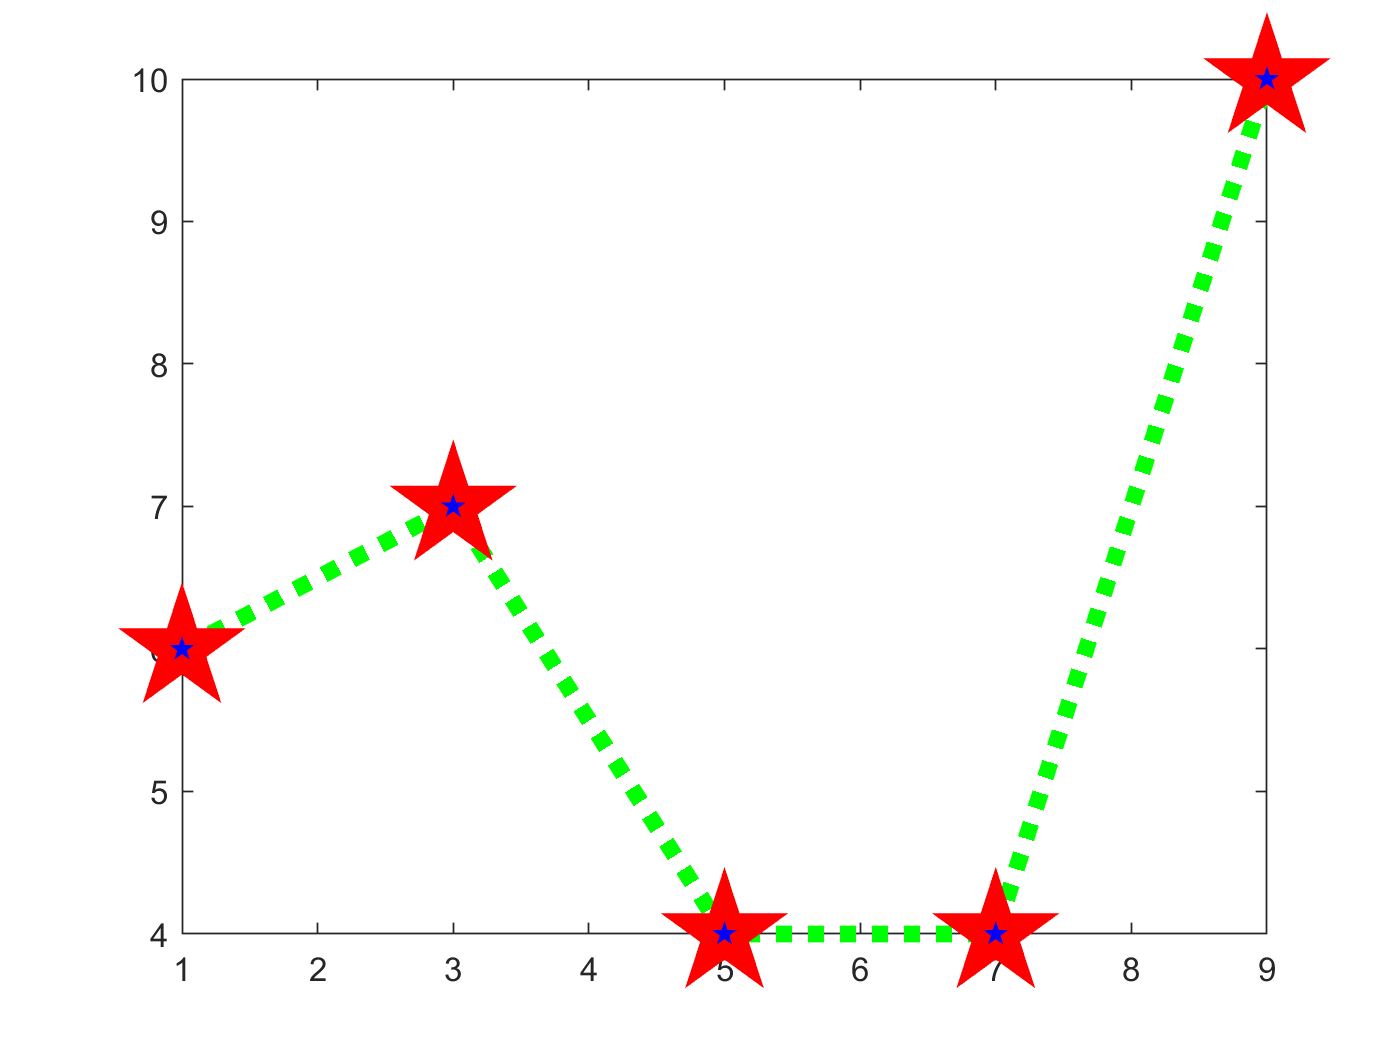

plot(x1,y1, 'marker','pentagram', 'markersize',24, 'markeredgecolor','r', ...
    'markerfacecolor','b', 'linestyle',':', 'color','g', 'linewidth',5);

Two plots on the same figure using "hold on", or extend plot()

disp('Two plots on the same set of axes')

Two plots on the same set of axes


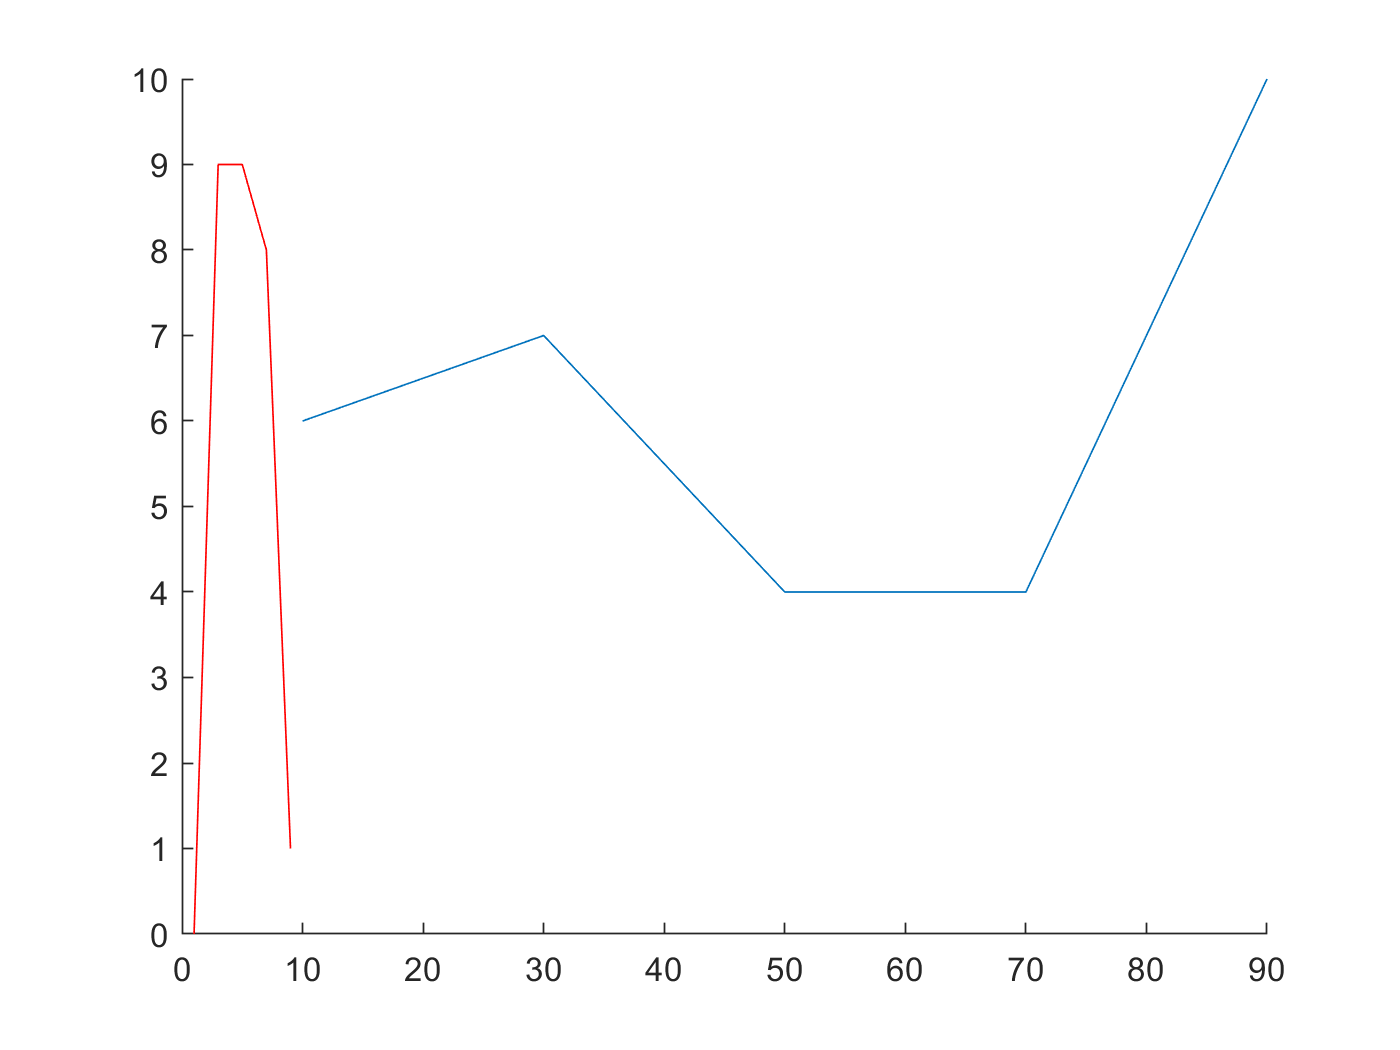

figure %If I remove this, chaos ensues
hold on %Plot thing in the same figure

x1 = [10 30 50 70 90];
y1 =[6 7 4 4 10];
plot(x1,y1)

x2 = [1 3 5 7 9];
y2 = [0 9 9 8 1];
plot(x2,y2,'r')

hold off %Turn off the monster


disp('Or we could do two plots on the same set of axes like this ...')

Or we could do two plots on the same set of axes like this ...


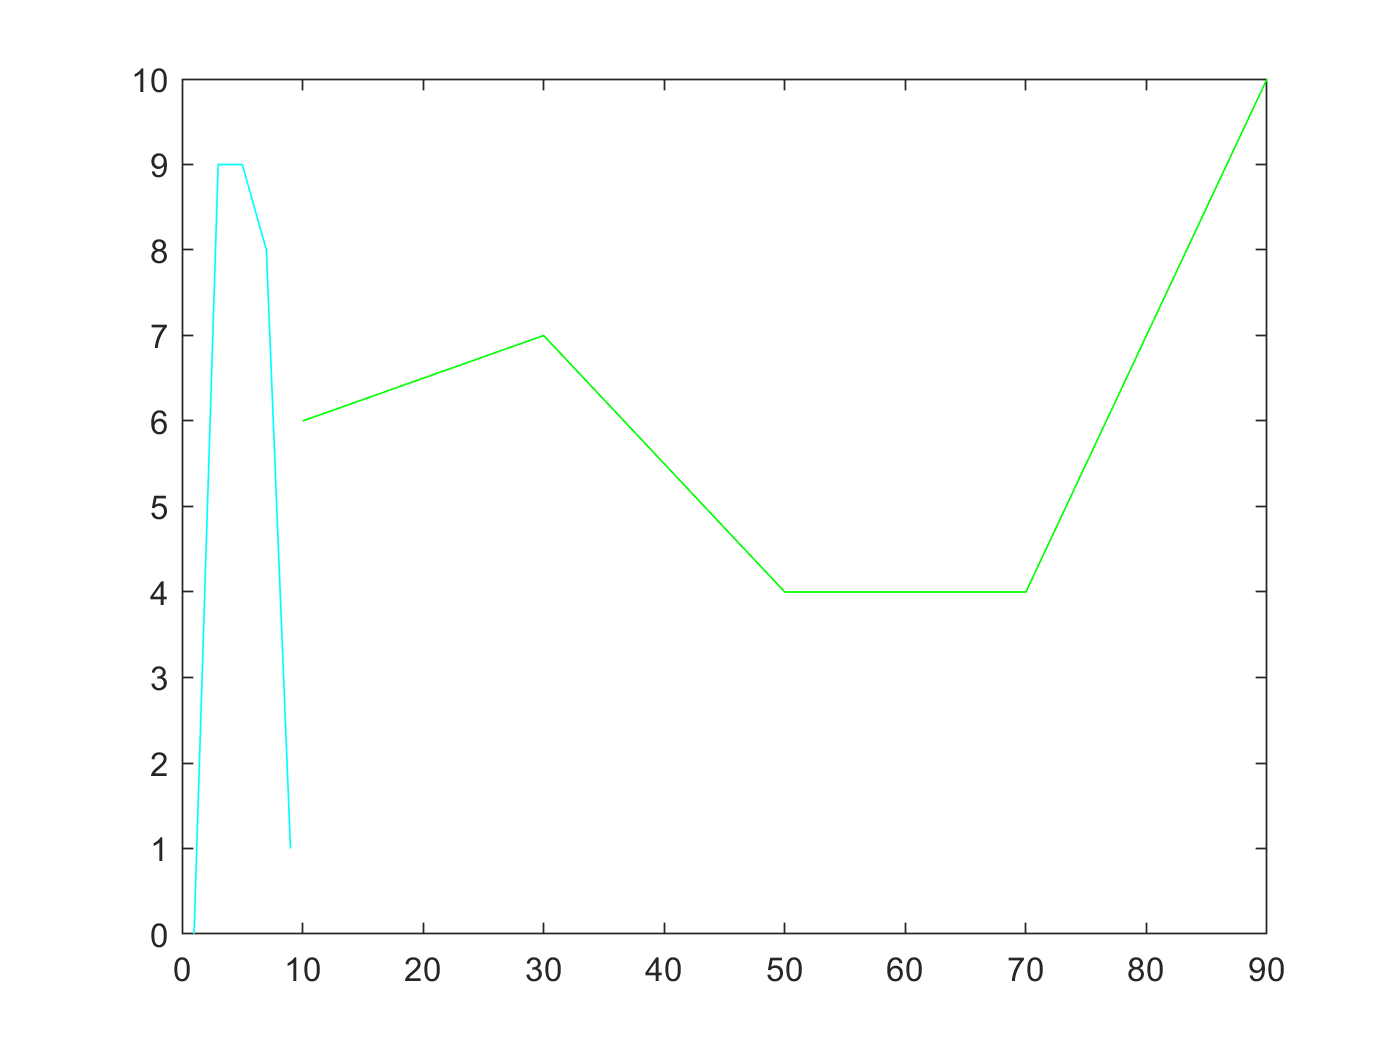

plot(x1,y1,'g',x2,y2,'c')

Axis control

disp('Axis Control')

Axis Control


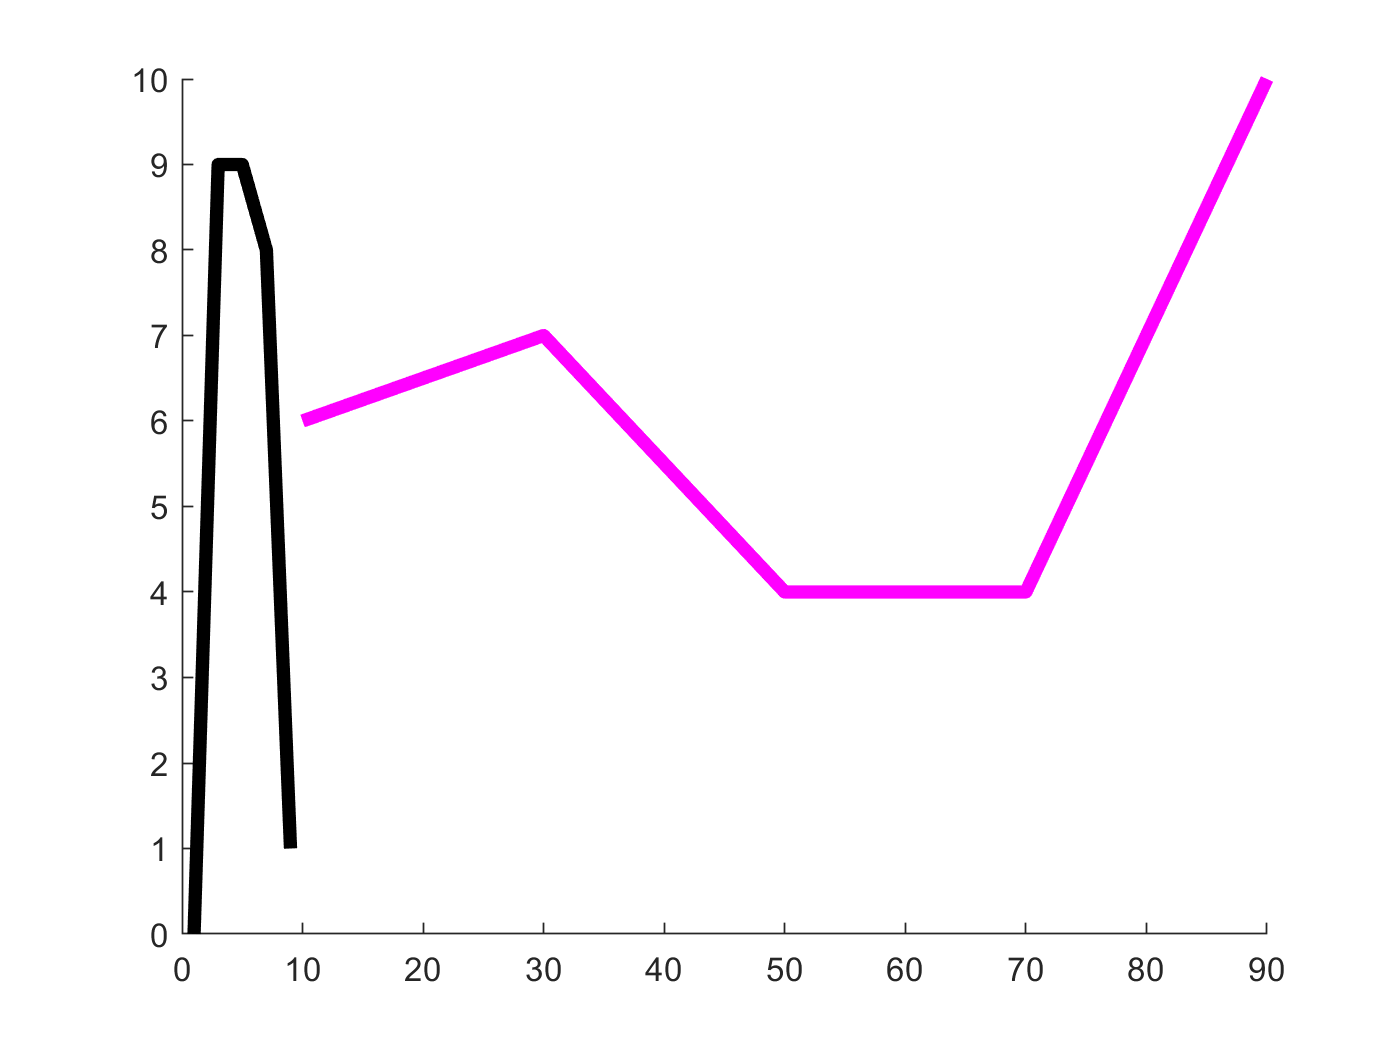

figure
hold on
x1 = [10 30 50 70 90];
y1 =[6 7 4 4 10];
plot(x1,y1,'m','linewidth',4)
x2 = [1 3 5 7 9];
y2 = [0 9 9 8 1];
plot(x2,y2,'k','linewidth',4)
hold off


% axis tight %sets the axis limits to the range of the data.
% axis equal %sets the aspect ratio so that equal tick mark increments on the x-,y- and z-axis are equal in size.
% axis square %makes the current axis box square in size.
% axis off
% axis([-20 20 -10 10])
% grid on 


Annotations

disp('Annotations')

Annotations


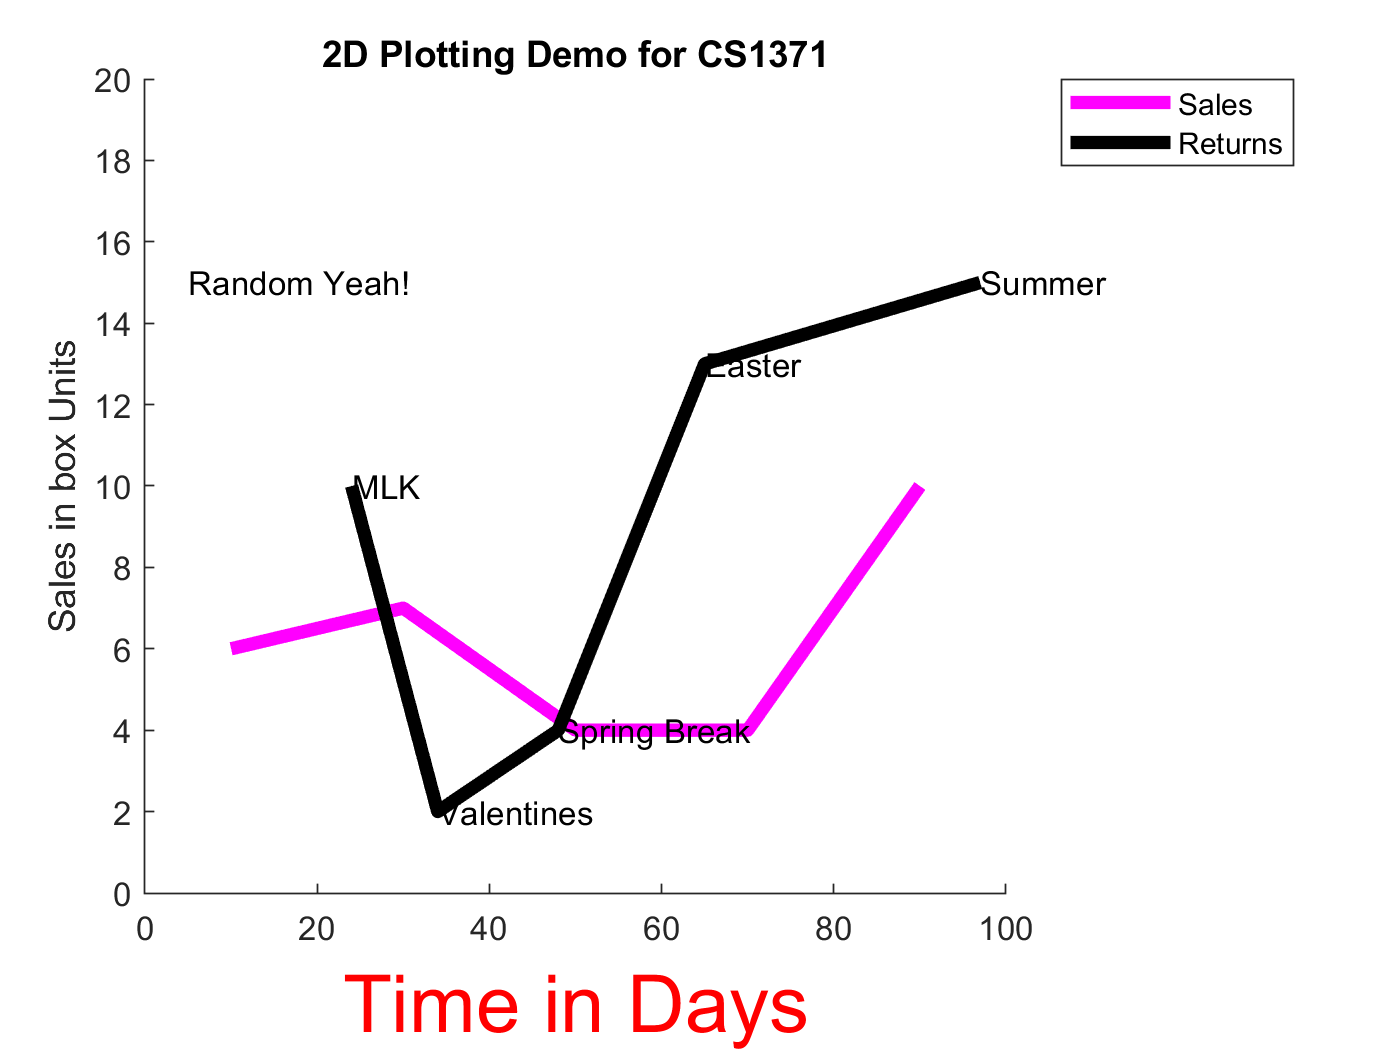

figure
hold on
x1 = [10 30 50 70 90];
y1 =[6 7 4 4 10];
plot(x1,y1,'m','linewidth',4)
x2 = [24 34 48 65 97];
y2 = [10 2 4 13 15];
plot(x2,y2,'k','linewidth',4)
hold off

axis([0 100 0 20])

%Comes after the plot
title('2D Plotting Demo for CS1371')
legend('Sales', 'Returns','Location','bestoutside')
% legend boxoff
text(5,15,'Random Yeah!')
text(x2,y2,{'MLK'; 'Valentines'; 'Spring Break'; 'Easter'; 'Summer'})
xlabel('Time in Days','fontsize',24,'color','r')
ylabel('Sales in box Units');

Subplots

disp('Subplots')

Subplots


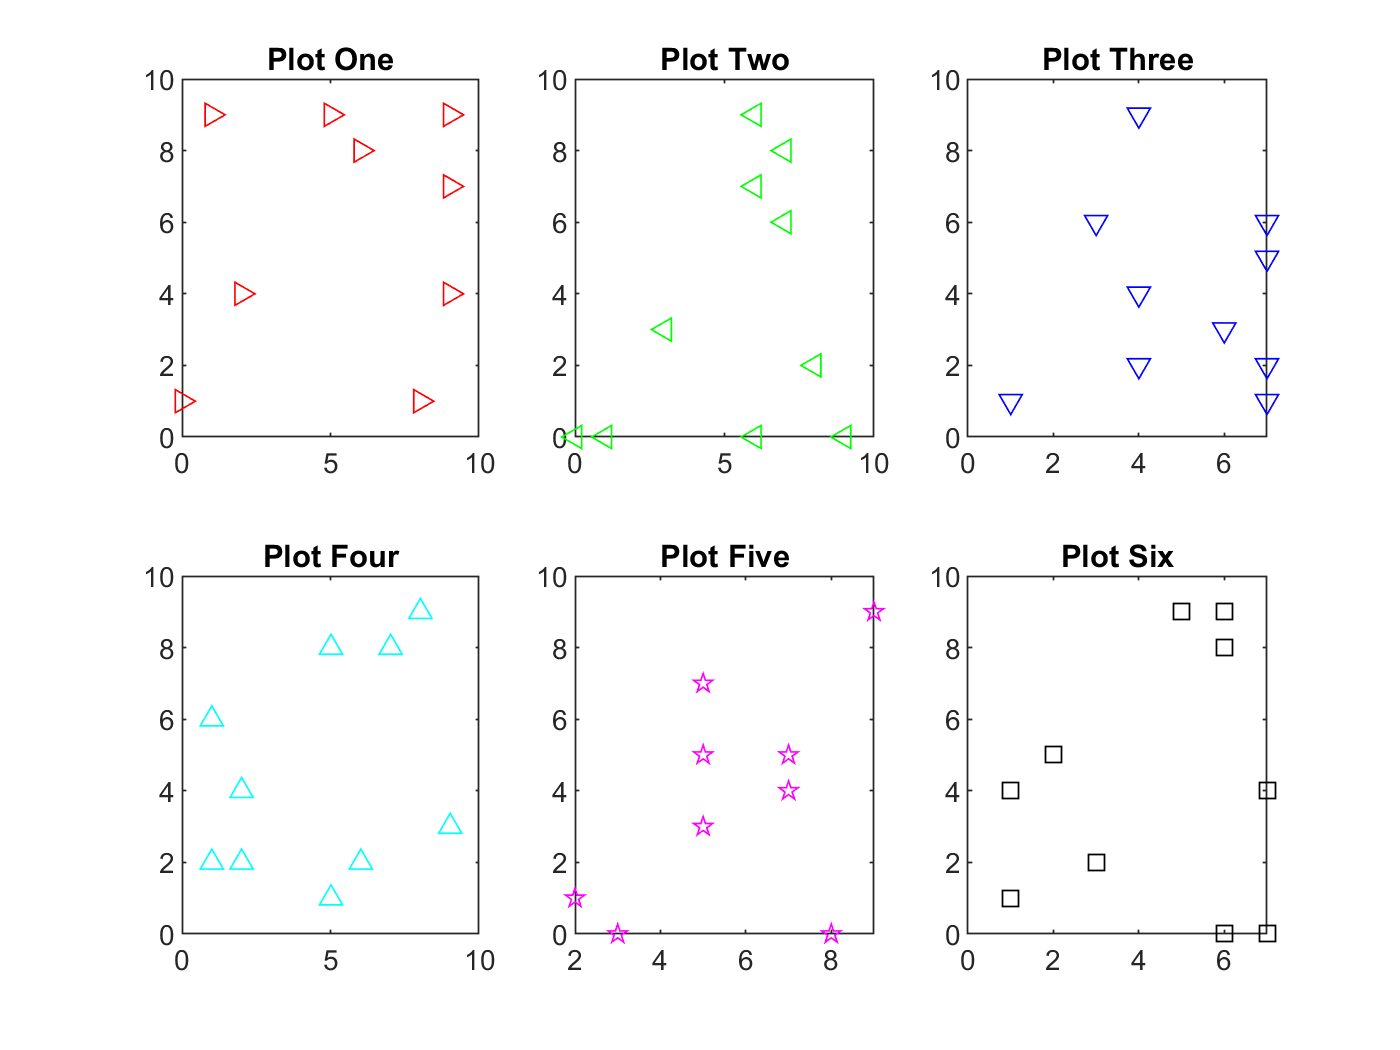

figure
% 
subplot(2,3,1)
x1 = floor(rand(1,10)*10);
y1 = floor(rand(1,10)*10);
plot(x1,y1,'r>')
title('Plot One')

subplot(2,3,2)
x1 = floor(rand(1,10)*10);
y1 = floor(rand(1,10)*10);
plot(x1,y1,'g<')
title('Plot Two')

subplot(2,3,3)
x1 = floor(rand(1,10)*10);
y1 = floor(rand(1,10)*10);
plot(x1,y1,'bv')
title('Plot Three')

subplot(2,3,4)
x1 = floor(rand(1,10)*10);
y1 = floor(rand(1,10)*10);
plot(x1,y1,'c^')
title('Plot Four')

subplot(2,3,5)
x1 = floor(rand(1,10)*10);
y1 = floor(rand(1,10)*10);
plot(x1,y1,'mp')
title('Plot Five')

subplot(2,3,6)
x1 = floor(rand(1,10)*10);
y1 = floor(rand(1,10)*10);
plot(x1,y1,'ks')
title('Plot Six')